%% POWER-GENERATIOM-SIM

initialTime = datetime(2022,12,14,1,4,0);
initialTimeJD = juliandate(initialTime);

mu = 3.986e14; % Graviational constant of Earth
Re = 6378e03;

% Orbital Parameters
sat.a = Re + 500e03;
sat.e = 0;
sat.i = deg2rad(97);
sat.RAAN = deg2rad(23);
sat.w = deg2rad(90);
sat.f = 0;


sat.n =sqrt(mu/(sat.a)^3);
sat.T = 2*pi/sat.n;

sat.G = 1300; %[w/M^2]
sat.eta = 0.335;

% Solar Panels (+X,+Y,-Y,-Z)
sat.np1 = [1;0;0];
sat.Ap1 = 0.7*10e-4;

sat.np2 = [0;1;0];
sat.Ap2 = 0.7*300e-4;

sat.np3 = [0;-1;0];
sat.Ap3 = 0.7*300e-4;

sat.np4 = [0;0;1];
sat.Ap4 = 0.7*300e-4;

sat.SPnormals = [sat.np1, sat.np2, sat.np3,sat.np4];
sat.SPareas = diag([sat.Ap1,sat.Ap2,sat.Ap3,sat.Ap4]);

model = 'PowerGenSim';
open_system(model);
simOut = sim(model);

positionTT = timeseries2timetable(simOut.yout{1}.Values);


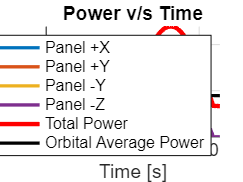


powerData = simOut.yout.get('Power');
power = powerData.Values.Data;
time = powerData.Values.Time;

power = squeeze(power)'; 
powerTotal = sum(power,2);

OAP = sum(mean(power,1));

% Plot the power of individual panels
% Define the custom labels for each panel
panel_labels = {'+X', '+Y', '-Y', '-Z'};

figure;
hold on
for i = 1:4
    plot(time,power(:,i), 'Linewidth',1.5,'DisplayName', ['Panel ' panel_labels{i}])
end
plot(time,powerTotal,'r' ,'Linewidth',2,'DisplayName', 'Total Power')
plot(time,OAP*ones(size(time)),'k','Linewidth',1.5,'DisplayName','Orbital Average Power')
hold off;

title('Power v/s Time')
xlabel('Time [s]');
ylabel('Power [W]');
legend;
grid on;

% startTime = initialTime;
% stopTime = startTime + seconds(sat.T);
% sampleTime = 1000;
% sc = satelliteScenario(startTime,stopTime,sampleTime);
% 
% SATEL = satellite(sc,positionTT,Name = "Spacecraft");
% 
% % Launch a satellite scenario viewer
% v = satelliteScenarioViewer(sc,CameraReferenceFrame = "ECEF");
% 
% play(sc);